## **Импорт данных**

close all
clear variables

adc = importdata("data\adc.csv") %файл с ожидаемым откликом RC-цепи

adc =      0
     0
     0
     4
     0
     3
     2
     0
     0
     9


theory = importdata("data\theory.csv") %файл с считанными значениями с АЦП с учётом шумов и выбросов

theory =      0
     0
     0
     0
     0
     0
     0
     0
     0
     0


settings = importdata("data\settings.csv") %файл с параметрами АЦП и эксперимента

settings = struct with fields:
          data: [13 100 3.3000 8]
      textdata: {'TMeasure'  'SamplingFrequency'  'VRef'  'Nadc'}
    colheaders: {'TMeasure'  'SamplingFrequency'  'VRef'  'Nadc'}



TMeasure = settings.data(1, 1) %общее время эксперимента

TMeasure = 13

Sampling_Frequency = settings.data(1, 2) %частота дискретизации АЦП

Sampling_Frequency = 100

VRef = settings.data(1, 3) %опорное напряжение АЦП

VRef = 3.3000

Nadc = settings.data(1, 4) %разрядность АЦП

Nadc = 8


adc_voltage = adc / (2^Nadc) * VRef %перевод значений АЦП в вольты

adc_voltage =          0
         0
         0
    0.0516
         0
    0.0387
    0.0258
         0
         0
    0.1160


time = (0 : (1/Sampling_Frequency) : TMeasure)

time =          0    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900


## Вычисление среднеквадратичной ошибки

S0 = sig_std_dev(adc_voltage, 20) %среднеквадратичная ошибка

S0 = 0.0287

## Фильтрация скользящего среднего

adc_voltage_meanfilt = transpose(meanfilt(adc_voltage, 10)) %фильтрация скользящего среднего

adc_voltage_meanfilt =     0.0052
    0.0090
    0.0116
    0.0116
    0.0116
    0.0232
    0.0232
    0.0258
    0.0258
    0.0219


S_meanfilt = sig_std_dev(adc_voltage_meanfilt, 20) %среднеквадратичная ошибка скользящего среднего

S_meanfilt = 0.0215

## Медианная фильтрация

adc_voltage_medianfilt = transpose(medianfilt(adc_voltage, 10)) %медианная фильтрация

adc_voltage_medianfilt =          0
         0
         0
         0
         0
         0
         0
    0.0129
    0.0129
    0.0064


S_medianfilt = sig_std_dev(adc_voltage_medianfilt, 20) %среднеквадратичная ошибка медианной фильтрации

S_medianfilt = 0.0213

### Фильтрация скользящего среднего для медианной фильтрации

adc_voltage_medianfilt_meanfilt =transpose(meanfilt(adc_voltage_medianfilt, 10)) %фильтр среднего для медианной фильтрации

adc_voltage_medianfilt_meanfilt =          0
         0
         0
    0.0013
    0.0026
    0.0032
    0.0039
    0.0045
    0.0045
    0.0045


S_medianfilt_meanfilt = sig_std_dev(adc_voltage_medianfilt_meanfilt, 20) %среднеквадратичная ошибка этого параметра

S_medianfilt_meanfilt = 0.0208

## Остальные графики

fg = figure

fg =   Figure (3) with properties:

      Number: 3
        Name: ''
       Color: [0.9400 0.9400 0.9400]
    Position: [520 378 560 420]
       Units: 'pixels'

  Show all properties


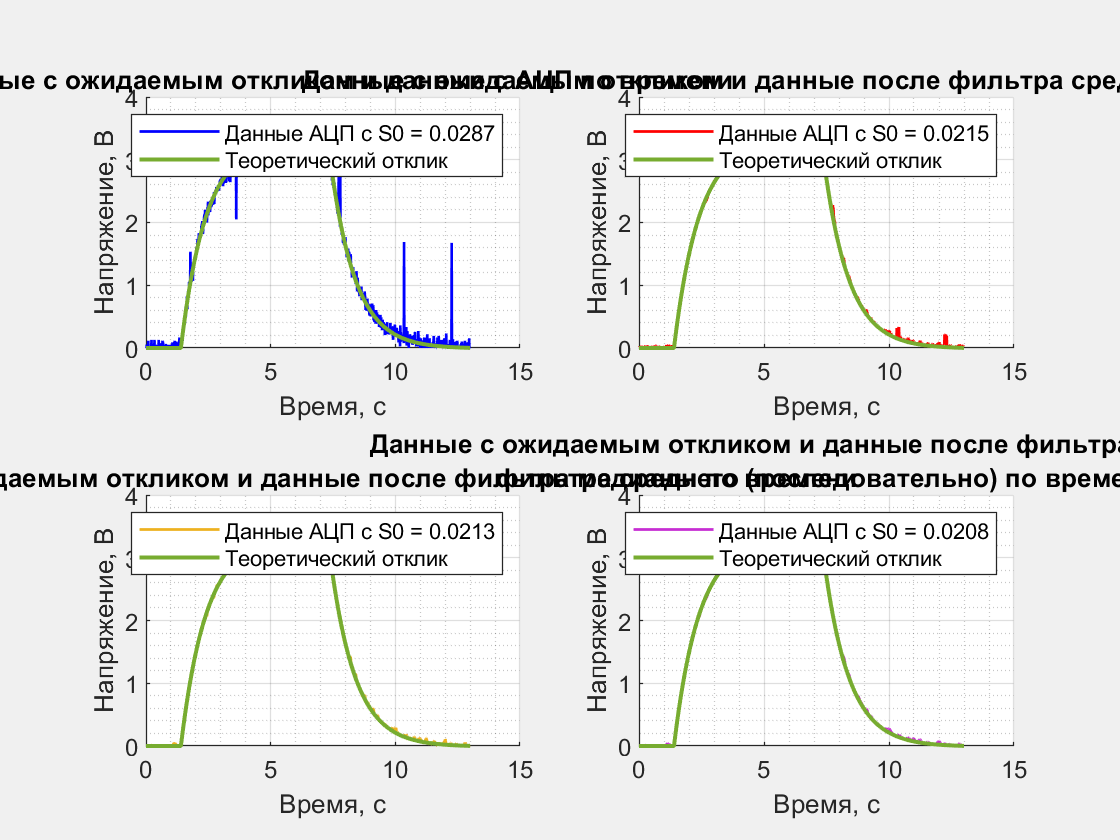

set(fg, "Visible", "on")

subplot(2,2,1)
hold on
plot(time, adc_voltage, 'b', 'LineWidth', 1)
plot(time, theory, 'Color', [0.4660 0.6740 0.1880], 'LineWidth', 1.5)
xlabel('Время, с')
ylabel('Напряжение, В')
grid on
grid minor
legendStr = sprintf('Данные АЦП c S0 = %.4f', S0);
legend(legendStr, 'Теоретический отклик')
title('Данные с ожидаемым откликом и данные с АЦП по времени')
hold off

subplot(2, 2, 2)
hold on
plot(time, adc_voltage_meanfilt, 'red', 'LineWidth', 1)
plot(time, theory, 'Color', [0.4660 0.6740 0.1880], 'LineWidth', 1.5)
xlabel('Время, с')
ylabel('Напряжение, В')
grid on
grid minor
legendStr = sprintf('Данные АЦП c S0 = %.4f', S_meanfilt);
legend(legendStr, 'Теоретический отклик')
title('Данные с ожидаемым откликом и данные после фильтра среднего по времени')
hold off

subplot(2, 2, 3)
hold on
plot(time, adc_voltage_medianfilt, 'Color', [0.9290 0.6940 0.1250], 'LineWidth', 1)
plot(time, theory, 'Color', [0.4660 0.6740 0.1880], 'LineWidth', 1.5)
xlabel('Время, с')
ylabel('Напряжение, В')
grid on
grid minor
legendStr = sprintf('Данные АЦП c S0 = %.4f', S_medianfilt);
legend(legendStr, 'Теоретический отклик')
title('Данные с ожидаемым откликом и данные после фильтра медианы по времени')
hold off

subplot(2, 2, 4)
hold on
plot(time, adc_voltage_medianfilt_meanfilt, 'Color', '#c62dd2', 'LineWidth', 1)
plot(time, theory, 'Color', [0.4660 0.6740 0.1880], 'LineWidth', 1.5)
xlabel('Время, с')
ylabel('Напряжение, В')
grid on
grid minor
legendStr = sprintf('Данные АЦП c S0 = %.4f', S_medianfilt_meanfilt);
legend(legendStr, 'Теоретический отклик')
title({'Данные с ожидаемым откликом и данные после фильтра медианы и'; 'фильтра среднего (последовательно) по времени'})
hold off

## Сохранение графика

saveas(fg, 'lab_2\signal.png')

Error using saveas
Invalid or missing path: lab_2\signal.png

function y = meanfilt(x, N)
    y = zeros(1, length(x));
    x = apdate(x, N);
    for i = 1 : (length(x) - (N - 1))
        y(i) = sum(x(i:i+(N-1)))/N;
    end
end

function y = medianfilt(x, N)
    y = zeros(1, length(x));
    x = apdate(x, N);
    for i = 1 : (length(x) - (N - 1))
        y(i) = median(x(i:i+(N-1)), "all");
    end
end

function x_new = apdate(x, N)
    if mod(N-1, 2) == 0
        for i = 1 : (N-1)/2
            x = [x(1, 1); x];
        end
        for i = 1 : (N-1)/2
            x = [x; x(length(x), 1)];
        end
    else
        for i = 1 : (N)/2
            x = [x(1, 1); x];
        end
        for i = 1 : (N-2)/2
            x = [x; x(length(x), 1)];
        end
    end
    x_new = x;
end